clc;clear;close all;

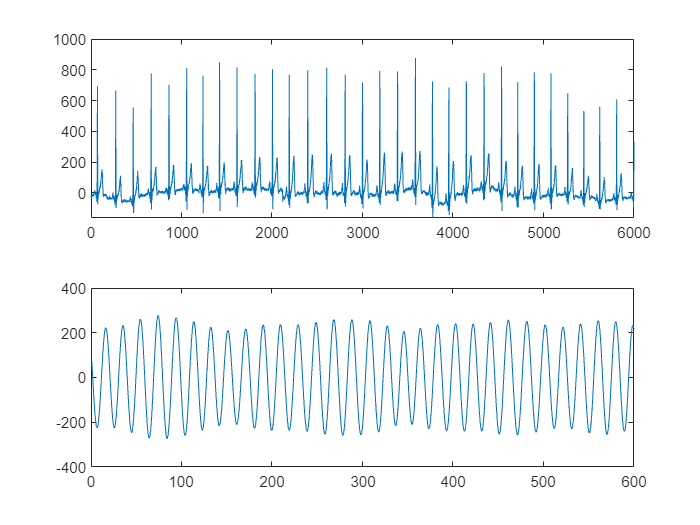

% a)
data = readtable('data.csv');
ECG = table2array(data(:,1)); 
PPG = table2array(data(:,2));
PPG = PPG(1:600);
subplot(2,1,1)
plot(ECG)
subplot(2,1,2)
plot(PPG)

% b)
fs_ecg = 200;  
fs_ppg = 20;   
window_size = 2; 
step_size = 1;    
window_ecg = window_size * fs_ecg;
step_ecg = step_size * fs_ecg;
window_ppg = window_size * fs_ppg;
step_ppg = step_size * fs_ppg;
hr_ecg = [];
hr_ppg = [];

% 滑动窗口计算心率
for i = 1:step_ecg:length(ECG) - window_ecg
    % ECG
    ecg_window = ECG(i:i+window_ecg-1);
    peaks_ecg = findpeaks(ecg_window,"MinPeakHeight",200,'MinPeakDistance',fs_ecg/2);
    num_peaks_ecg = length(peaks_ecg);
    hr_ecg = [hr_ecg, (num_peaks_ecg / window_size) * 60];
end
for i = 1:step_ppg:length(PPG) - window_ppg
    % ECG
    ppg_window = PPG(i:i+window_ppg-1);
    peaks_ppg = findpeaks(ppg_window,"MinPeakHeight",3,'MinPeakDistance',fs_ppg/2);
    num_peaks_ppg = length(peaks_ppg);
    hr_ppg = [hr_ppg, (num_peaks_ppg / window_size) * 60];
end

% c)
% 计算MAE
mae = mean(abs(hr_ecg - hr_ppg));
fprintf('平均绝对误差 (MAE) 为: %.2f\n', mae);

平均绝对误差 (MAE) 为: 11.79


% d)
[peaks_ppg, locs_ppg] = findpeaks(PPG); % 阈值可调整
ibi = diff(locs_ppg) / fs_ppg; 
% 计算RMSSD
rmssd = sqrt(mean(diff(ibi).^2));

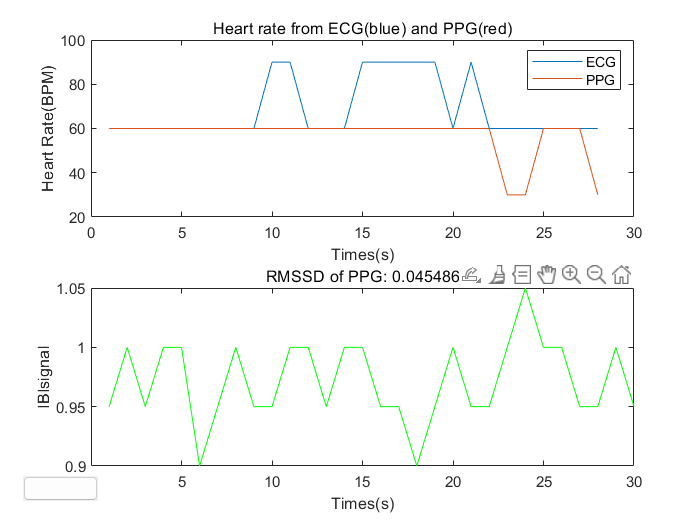

% e)
figure
subplot(2,1,1)
plot(hr_ecg)
hold on 
plot(hr_ppg)
hold on 
title('Heart rate from ECG(blue) and PPG(red)');
xlabel('Times(s)');
ylabel('Heart Rate(BPM)');
legend('ECG','PPG');uicontrol
subplot(2,1,2)
plot(ibi,'g-')
title(sprintf('RMSSD of PPG: %f',rmssd));
xlabel('Times(s)');
ylabel('IBIsignal');